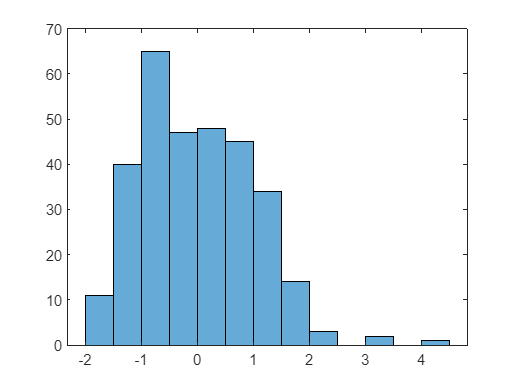

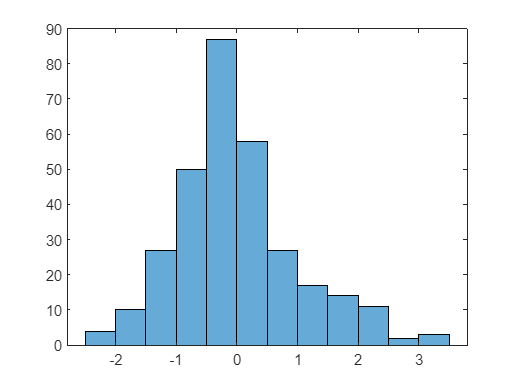

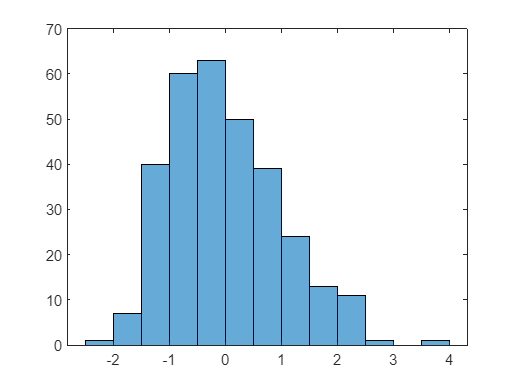

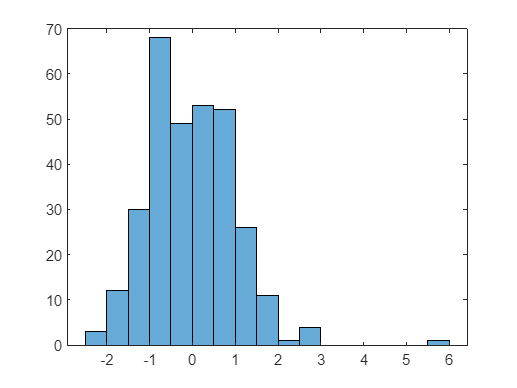

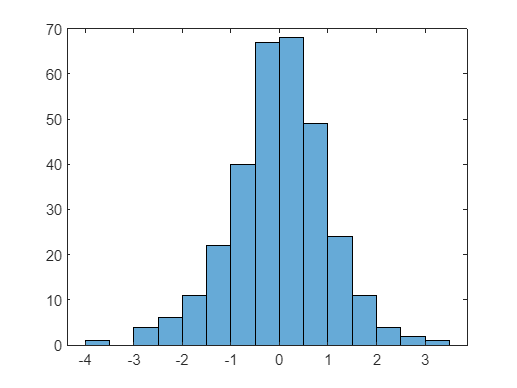

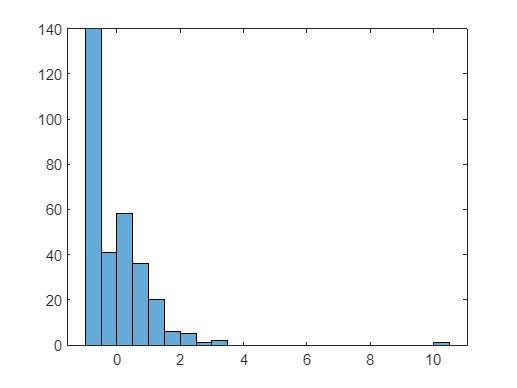

clear all; close all; clc

features = load('datasetTC4.dat');
[rowf,colf] = size(features);
m_feat = mean(features);
std_feat = std(features);
max_feat = max(features);
min_feat = min(features);
normtype = 'z-score';
norm_feat = [];
switch(normtype)
    case 'none'
    case 'z-score'
        for i=1:1:rowf
            norm_feat(i,:) = (features(i,:)-m_feat)./std_feat;
        end
        features = norm_feat;
    case 'range1'
        for i=1:1:rowf
            norm_feat(i,:) = (features(i,:)-min_feat)./(max_feat-min_feat);
        end
        features = norm_feat;
end

for i=1:1:colf
    figure
    histogram(features(:,i))
end

maxval = max(features)

maxval =     4.0226    3.1861    3.9781    5.8465    3.3902   10.4434


minval = min(features)

minval =    -1.9927   -2.4073   -2.0444   -2.2040   -3.5923   -0.9946


01. K-mean and K-median implementation

1.1 Estimate K using Dunn, Davis-Bouldin and Calinski

K-MEAN

tic
Nr = 50; % number of iterations inside k-means
Ne = 100; % number of iterations to choose the ideal K
Kt = 6; % number of prototypes

for a=1:1:Ne
    for K=2:1:Kt
        % Initialization - select number of classes and initial prototypes
        P = randperm(rowf,K);
        P = sort(P);
        n_fea = features;
        w = [];
        C = [];
        Cinv = [];
        mean_i = [];
        mi = [];
        wmean_f = [];
        V = [];
        W = [];
        
        w = features(P,:);
        n_fea = features;
        [r,c] = size(n_fea);

        for t=1:1:Nr

            % Determine partition and mean calculation
            l_group = [];
            d = [];
            aux = [];
            for i=1:1:r
                for j=1:1:K
                    aux = n_fea(i,:);
                    d(j) = norm(aux - w(j,:),2);
                end
            
                [dmin,I] = min(d);
                aux = [aux,I];
                l_group = [l_group;aux];
            end
            for i=1:1:K
                [rowx,col] = find(l_group(:,end)==i);
                Vi{t,i} = n_fea(rowx,:);
                if size(Vi{t,i})~=1
                    mean_i(i,:) = mean(Vi{t,i});
                else
                    mean_i(i,:) = Vi{t,i};
                end
            end

            % SSD
            aux2 = 0;
            for i=1:1:K
                [N(i),col] = size(Vi{t,i});
                s = [];
                aux1 = Vi{t,i};
                for j=1:1:N(i)
                    s(j) = norm(aux1(j,:) - w(i,:),2);
                end
                aux2 = aux2 + sum(s.^2);
            end
    
            W{t} = w;
            w = mean_i;
            SSD(t) = aux2;
        end

        [dmin,I] = min(SSD);
        wmean_f = W{I};
        for t=1:size(Vi,2)
            V{t} = Vi{I,t};
        end

        % Dunn
    
        % Dissimilarity
        pairs = [];
        for i=1:1:K
            for j=1:1:K
                if i~=j
                    aux = [i,j];
                    aux = sort(aux);
                    pairs = [pairs; aux];
                end
            end
        end
        pairs = unique(pairs,'rows');
        comb = size(pairs,1);
    
        aux1 = [];
        aux2 = [];
    
    
        for u=1:1:comb
            aux1 = V{pairs(u,1)};
            aux2 = V{pairs(u,2)};
            [r1,c] = size(aux1);
            [r2,c] = size(aux2);
            elem = [];
            for i=1:1:r1
                for j=1:1:r2
                    if i~=j
                        aux = [i,j];
                        aux = sort(aux);
                        elem = [elem; aux];
                    end
                end
            end
            elem = unique(elem,'rows');
            comb1 = size(elem,1);
            if r1==max(elem(:,2))
                aux1 = V{pairs(u,2)};
                aux2 = V{pairs(u,1)};
            end
            for i=1:1:comb1
                d(i) = norm(aux1(elem(i,1),:)-aux2(elem(i,2),:),2);
            end
            [dmin(u),I] = min(d);
        end
    
        d_Vimin = min(dmin);
    
        % Similarity
        for u=1:1:K
            aux1 = V{u};
            [r1,c] = size(aux1);
            elem = [];
            for i=1:1:r1
                for j=1:1:r1
                    if i~=j
                        aux = [i,j];
                        aux = sort(aux);
                        elem = [elem; aux];
                    end
                end
            end
            elem = unique(elem,'rows');
            comb1 = size(elem,1);
            for i=1:1:comb1
                d(i) = norm(aux1(elem(i,1),:)-aux1(elem(i,2),:),2);
            end
            [dmax(u),I] = max(d);
        end
    
        d_Vlmax = max(dmax);
    
        % CHOOSE THE GREATER DI
        DI(K,a) = d_Vimin/d_Vlmax;
    
        % Davis-Bouldin
        pairs = [];
        for i=1:1:K
            for j=1:1:K
                if i~=j
                    aux = [i,j];
                    aux = sort(aux);
                    pairs = [pairs; aux];
                end
            end
        end
        pairs = unique(pairs,'rows');
        comb = size(pairs,1);
    
        num = unique(pairs(:,1));
        tnum = length(num);
        aux = pairs(:,1);
        q = 2;
        Sj = [];
        Si = [];
        Rij = [];
    
        for i=1:1:tnum
            aux1 = V{i};
            aux2 = 0;
            [N(i),c] = size(aux1);
            for j=1:1:N(i)  
                di(j) = norm(aux1(j,:) - wmean_f(i,:),2);
            end
            aux2 = aux2 + sum(di.^q);
            Si(i) = (aux2/N(i))^(1/q);
    
            ind = find(aux==num(i));
            indn = length(ind);
    
            t=q;
            
            for j=1:1:indn
                aux1 = V{pairs(ind(j),2)};
                aux2 = 0;
                [N(j),c] = size(aux1);
                for u=1:1:N(j)  
                    dj(u) = norm(aux1(u,:) - wmean_f(j,:),2);
                end
                aux2 = aux2 + sum(dj.^q);
                Sj(j) = (aux2/N(j))^(1/q);
                dij(j) = norm(wmean_f(i,:)-wmean_f(pairs(ind(j),2),:),2);
                Sij(j) = (Si(i)+Sj(j))/dij(j);
            end
    
            [Rij(i),I] = max(Sij);
        end
    
        % The least value the better
        DB(K,a) = sum(Rij)/K;
    
        % Calinski-Harabasz
        C = [];
        Sb = zeros(colf);
        Sw = zeros(colf);
        for i=1:1:K
            [N(i),c] = size(V{i});
            aux = V{i};
            Sw = Sw+(N(i)*cov(aux));
            sub = (wmean_f(i,:)-m_feat)'; 
            Sb = Sb+(N(i)*sub*sub');
        end
    
        % Greater CH value
        num = trace(Sb)/(K-1);
        den = trace(Sw)/(rowf-K);
        CH(K,a) = num/den;
    end   
end

% Kopt
DI(1,:) = [];
DB(1,:) = [];
CH(1,:) = [];

% Dunn Index - Optimal value
[DImax, I] = max(DI);
K_DI = mode(I)+1

K_DI = 5

% Davies-Bouldin Index - Optimal value
[DBmin, I] = min(DB);
K_DB = mode(I)+1

K_DB = 2

% Calinski-Harabasz Index - Optimal value
[CHmax, I] = max(CH);
K_CH = mode(I)+1

K_CH = 2

% Processing time
final=toc

final = 1.1634e+03

1.2 Compare the final positions between k-means and k-median

K-MEANS

% Initialization - select number of classes and initial prototypes
Nr = 100; % number of iterations
K = 2;
P = randperm(rowf,K);
P = sort(P);
n_fea = features;
w = [];
C = [];
Cinv = [];
mean_i = [];
mi = [];
wmean_f = [];
V = [];
W = [];
Vi = [];
SSD = [];

w = features(P,:);
n_fea = features;
[r,c] = size(n_fea);
wmean_i = w;

for t=1:1:Nr

    % Determine partition and mean calculation
    l_group = [];
    d = [];
    aux = [];
    for i=1:1:r
        for j=1:1:K
            aux = n_fea(i,:);
            d(j) = norm(aux - w(j,:),2);
        end
    
        [dmin,I] = min(d);
        aux = [aux,I];
        l_group = [l_group;aux];
    end
    for i=1:1:K
        [rowx,col] = find(l_group(:,end)==i);
        Vi{t,i} = n_fea(rowx,:);
        mean_i(i,:) = mean(Vi{t,i});
    end

    % SSD
    aux2 = 0;
    for i=1:1:K
        [N(i),col] = size(Vi{t,i});
        s = [];
        aux1 = Vi{t,i};
        for j=1:1:N(i)
            s(j) = norm(aux1(j,:) - w(i,:),2);
        end
        aux2 = aux2 + sum(s.^2);
    end

    W{t} = w;
    w = mean_i;
    SSD(t) = aux2;
end

[dmin,I] = min(SSD);
wmean_f = W{I};

K-MEDIAN

K = 2; % number of prototypes
[rowf,colf] = size(features);

% Initialization - select number of classes and initial prototypes
K = 2;
P = randperm(rowf,K);
P = sort(P);
n_fea = features;
w = [];
C = [];
Cinv = [];
median_i = [];
mi = [];
wmedian_f = [];
V = [];
W = [];
Vi = [];
SSD = [];

w = features(P,:);
n_fea = features;
[r,c] = size(n_fea);
wmedian_i = w;

for t=1:1:Nr

    % Determine partition and mean calculation
    V = [];
    l_group = [];
    for i=1:1:r
        for j=1:1:K
            aux = n_fea(i,:);
            d(j) = norm(aux - w(j,:),1);
        end
    
        [dmin,I] = min(d);
        aux = [aux,I];
        l_group = [l_group;aux];
    end
    for i=1:1:K
        [rowx,col] = find(l_group(:,end)==i);
        V{i} = n_fea(rowx,:);
        median_i(i,:) = median(V{i});
    end

    % SSD
    aux2 = 0;
    for i=1:1:K
        [N(i),col] = size(V{i});
        s = [];
        aux1 = V{i};
        for j=1:1:N(i)
            s(j) = norm(aux1(j,:) - w(i,:),1);
        end
        aux2 = aux2 + sum(s.^2);
    end

    W{t} = w;
    w = median_i;
    SSD(t) = aux2;
end

[dmin,I] = min(SSD);

wmedian_f = W{I};

% Prototypes final position - k-means
wmean_f

wmean_f =     0.9571    0.6037    0.8912    0.7789   -0.2571    0.7299
   -0.6642   -0.4190   -0.6185   -0.5405    0.1784   -0.5065


% Prototypes final position - k-median
wmedian_f

wmedian_f =     0.8136    0.2940    0.6319    0.7581   -0.2794    0.4381
   -0.7334   -0.4085   -0.7239   -0.6179    0.2489   -0.6323


aux2 = 0;
for i=1:1:size(wmedian_f,1)
    d_w(i) = norm(wmean_f(i,:)-wmedian_f(i,:));
end
% Distance between prototype
d_w

d_w =     0.5195    0.2068


1.2.(II)

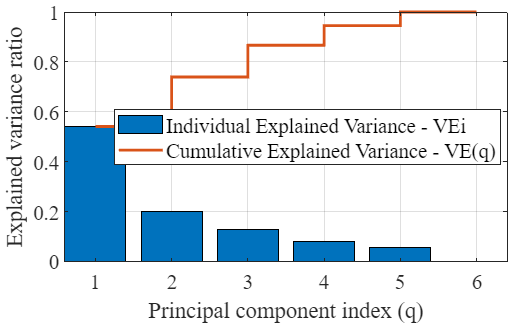

% First step

m=mean(features);
[rpca cpca] = size(features);
M = zeros(rpca,cpca);
for j=1:1:rpca
    M(j,:) = m;
end
n_feat = features - M;
Cx = cov(n_feat);

[U D V] = svd(Cx);
D = diag(D);

% Third Step
aux = 0;
for i=1:1:length(D)
    VEi(i) = D(i)/sum(D);
    VE(i) = aux+VEi(i);
    aux = VE(i);
end
VEi = VEi';
VE = VE';

X = n_feat';

plotVE(VEi, VE, 'Principal component index (q)', 'Explained variance ratio', ["Individual Explained Variance - VEi","Cumulative Explained Variance - VE(q)"])

% PCA dimension reduction
% tol = 0.90;
% q = find(VE<=tol);
q = [1;2];
Vq = V(:,q);
Q = Vq';
Z = Q*X;

K-MEAN

% Initialization - select number of classes and initial prototypes
Nr = 100; % number of iterations
K = 2;
[rowf,colf] = size(Z');
P = randperm(rowf,K);
P = sort(P);

w = [];
C = [];
Cinv = [];
mean_i = [];
mi = [];
wmean_f = [];
V = [];
W = [];
Vi = [];
SSD = [];

n_fea = Z';
w = n_fea(P,:);
[r,c] = size(n_fea);
wmean_i = w;

for t=1:1:Nr

    % Determine partition and mean calculation
    
    l_group = [];
    d = [];
    aux = [];
    for i=1:1:r
        for j=1:1:K
            aux = n_fea(i,:);
            d(j) = norm(aux - w(j,:),2);
        end
    
        [dmin,I] = min(d);
        aux = [aux,I];
        l_group = [l_group;aux];
    end
    for i=1:1:K
        [rowx,col] = find(l_group(:,end)==i);
        Vi{t,i} = n_fea(rowx,:);
        mean_i(i,:) = mean(Vi{t,i});
    end

    % SSD
    aux2 = 0;
    for i=1:1:K
        [N(i),col] = size(Vi{t,i});
        s = [];
        aux1 = Vi{t,i};
        for j=1:1:N(i)
            s(j) = norm(aux1(j,:) - w(i,:),2);
        end
        aux2 = aux2 + sum(s.^2);
    end

    W{t} = w;
    w = mean_i;
    SSD(t) = aux2;
end

[dmin,I] = min(SSD);
wmean_f = W{I};

K-MEDIAN

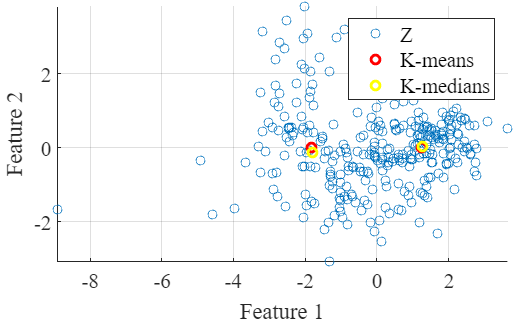

K = 2; % number of prototypes
[rowf,colf] = size(Z');

% Initialization - select number of classes and initial prototypes
K = 2;
P = randperm(rowf,K);
P = sort(P);

w = [];
C = [];
Cinv = [];
median_i = [];
mi = [];
wmedian_f = [];
V = [];
W = [];
Vi = [];
SSD = [];

n_fea = Z';
w = n_fea(P,:);
[r,c] = size(n_fea);
wmedian_i = w;

for t=1:1:Nr

    % Determine partition and mean calculation
    V = [];
    l_group = [];
    for i=1:1:r
        for j=1:1:K
            aux = n_fea(i,:);
            d(j) = norm(aux - w(j,:),1);
        end
    
        [dmin,I] = min(d);
        aux = [aux,I];
        l_group = [l_group;aux];
    end
    for i=1:1:K
        [rowx,col] = find(l_group(:,end)==i);
        V{i} = n_fea(rowx,:);
        median_i(i,:) = median(V{i});
    end

    % SSD
    aux2 = 0;
    for i=1:1:K
        [N(i),col] = size(V{i});
        s = [];
        aux1 = V{i};
        for j=1:1:N(i)
            s(j) = norm(aux1(j,:) - w(i,:),1);
        end
        aux2 = aux2 + sum(s.^2);
    end

    W{t} = w;
    w = median_i;
    SSD(t) = aux2;
end

[dmin,I] = min(SSD);

wmedian_f = W{I};

n_fea1 = n_fea(:,1);
n_fea2 = n_fea(:,2);

wmean_f1 = wmean_f(:,1);
wmean_f2 = wmean_f(:,2);

wmedian_f1 = wmedian_f(:,1);
wmedian_f2 = wmedian_f(:,2);

plotscatter4(n_fea1, n_fea2, wmean_f1, wmean_f2, wmedian_f1, wmedian_f2, 'Feature 1', 'Feature 2', ["Z","K-means","K-medians"])

wmean_f

wmean_f =    -1.8342    0.0158
    1.2394   -0.0107


wmedian_f

wmedian_f =    -1.8061   -0.1272
    1.2567    0.0166



aux2 = 0;
for i=1:1:size(wmedian_f,1)
    d_w(i) = norm(wmean_f(i,:)-wmedian_f(i,:));
end
d_w

d_w =     0.1458    0.0324


K-MEANS

% Initialization - select number of classes and initial prototypes
Nr = 100; % number of iterations
K = 2;
[rowf,colf] = size(features);
P = randperm(rowf,K);
P = sort(P);
n_fea = features;
w = [];
C = [];
Cinv = [];
mean_i = [];
mi = [];
wmean_f = [];
V = [];
W = [];
Vi = [];
SSD = [];


n_fea = features;
w = n_fea(P,:);
[r,c] = size(n_fea);
wmean_i = w;

for t=1:1:Nr

    % Determine partition and mean calculation
    l_group = [];
    d = [];
    aux = [];
    for i=1:1:r
        for j=1:1:K
            aux = n_fea(i,:);
            d(j) = norm(aux - w(j,:),2);
        end
    
        [dmin,I] = min(d);
        aux = [aux,I];
        l_group = [l_group;aux];
    end
    for i=1:1:K
        [rowx,col] = find(l_group(:,end)==i);
        Vi{t,i} = n_fea(rowx,:);
        mean_i(i,:) = mean(Vi{t,i});
    end

    % SSD
    aux2 = 0;
    for i=1:1:K
        [N(i),col] = size(Vi{t,i});
        s = [];
        aux1 = Vi{t,i};
        for j=1:1:N(i)
            s(j) = norm(aux1(j,:) - w(i,:),2);
        end
        aux2 = aux2 + sum(s.^2);
    end

    W{t} = w;
    w = mean_i;
    SSD(t) = aux2;
end

[dmin,I] = min(SSD);
% Prototypes final position
wmean_f = W{I}

wmean_f =     0.9885    0.6324    0.9034    0.7978   -0.2565    0.7521
   -0.6502   -0.4160   -0.5942   -0.5247    0.1687   -0.4947



for i=1:1:K
    Vi_f = Vi{I,i};
    n_ele(i) = size(Vi_f,1);
    Cluster{i,:} = [min(Vi_f)',max(Vi_f)',mean(Vi_f)',median(Vi_f)',std(Vi_f)'];
    % Cluster statistics 
    Cluster{i,:}
    % Cluster size
    size(Vi_f)
end

ans =    -0.1727    4.0226    0.9885    0.9175    0.6537
   -1.2263    3.1861    0.6324    0.3714    1.0169
   -1.0473    3.9781    0.9034    0.7874    0.7926
   -1.7630    5.8465    0.7978    0.8207    0.9026
   -3.5923    2.5470   -0.2565   -0.2291    1.0951
   -0.7119   10.4434    0.7521    0.6732    1.1820


ans =    123     6


ans =    -1.9927    0.8084   -0.6502   -0.6786    0.5566
   -2.4073    2.3998   -0.4160   -0.4020    0.7380
   -2.0444    1.4099   -0.5942   -0.6242    0.5954
   -2.2040    1.1850   -0.5247   -0.5613    0.6552
   -2.9225    3.3902    0.1687    0.1854    0.8958
   -0.9946    0.7626   -0.4947   -0.6179    0.3532


ans =    187     6
